clearvars;
I = imread('MH23.jpeg');
I = I(1:375,:,3);

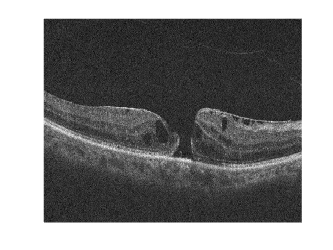

figure;
I = im2double(I);
imagesc(I); colormap gray;
%title('Original')
In = [zeros(1,750);I ;I(end:-1:1,:)];
axis off

% figure;
% imshow(In);

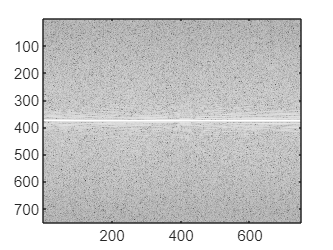

Ifft = fftshift(fft(In),1);
figure;
%imshow(real(Ifft))
imagesc(10*log10(abs(Ifft))); colormap gray;

% figure;
% plot(I(:,300))
% figure;
% plot(real(Ifft(:,300)))

%Delay line

N1 = 100;
PSD = Ifft;
PSD_half = PSD(375-N1/2+1:375+N1/2,:);
Acap1 = PSD_half;
a1 = ifft(ifftshift(Acap1,1));

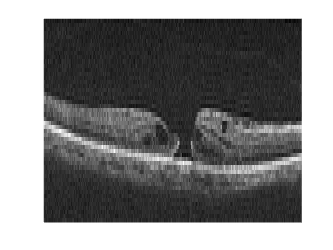

figure;
imagesc(abs(a1(1:N1/2,:))); colormap gray;
axis off

delay = exp(1i*(0:pi/N1:pi*(1-1/N1)))'*ones(1,750);
Acap2 = Acap1.*delay;
a2 = ifft(ifftshift(Acap2,1));

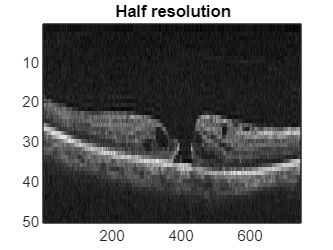

figure;
imagesc(abs(a2(1:N1/2,:))); colormap gray;
title('Half resolution')

a_rec = zeros(N1*2,750);
a_rec(1:2:end-1,:) = a2;
a_rec(2:2:end,:) = a1;

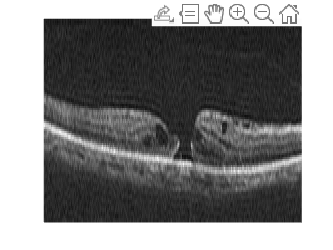

figure;
imagesc(abs(a_rec(1:N1,:))); colormap gray;
%title('Reconstructed - Full resolution')
axis off

%%%%%%%  Cross-phase modulation %%%%%%

PSD_downsample = PSD(1:2:end,:);

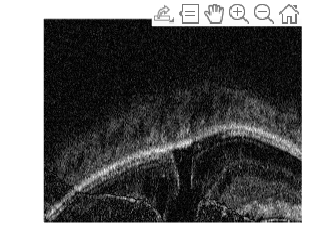

a_d = ifft(PSD_downsample);
a_det = ifft(PSD);
imagesc(abs(a_d(1:188,:))); colormap gray;
%title('Half depth')
axis off

A1 = 2;
A2 = 1;
f11 = 1/4;
f12 = 1/2;
f21 = 1/4;
f22 = 1/2;

N = 376;
tau_vec = (-10*(N-1):1:10*(N-1))/(2*N);
Mod11 = exp(1i*A1*sin(2*pi*f11*tau_vec));
Mod12 = exp(1i*A1*sin(2*pi*f12*tau_vec));
r0 = xcorr(Mod11,Mod12,'unbiased');
H0 = r0((size(r0,2)+1)/2-N+1:(size(r0,2)+1)/2+N-1);

Mod21 = exp(1i*A2*sin(2*pi*f21*tau_vec));
Mod22 = exp(1i*A2*sin(2*pi*f22*tau_vec));
r1 = xcorr(Mod21,Mod22,'unbiased');
H1 = r1((size(r1,2)+1)/2-N+1:(size(r1,2)+1)/2+N-1);

H0n = fftshift(H0);
H1n = fftshift(H1);

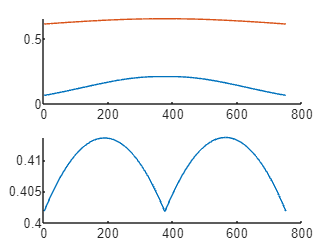


figure;
subplot(2,1,1)
hold on;
% plot(real(Mod1));
% plot(real(Mod2));
%plot(real(r12));
%plot(abs(r12));
plot(real(H0));
plot(real(H1));
%plot(real(H0c));
subplot(2,1,2)
hold on;
plot(real(H1).*real(H1n));

h0 = fftshift(ifft(ifftshift(H0)));
h0n = fftshift(ifft(ifftshift(H0n)));

h1 = fftshift(ifft(ifftshift(H1)));
h1n = fftshift(ifft(ifftshift(H1n)));

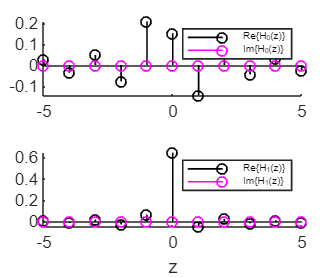



figure;
subplot(2,1,1);
hold on;
stem(-5:5,real(h0(N-5:N+5)),'LineWidth',1,'Color','k');
stem(-5:5,imag(h0(N-5:N+5)),'LineWidth',1,'Color','m');

lgd = legend('Re\{H_0(z)\}','Im\{H_0(z)\}');
lgd.FontSize = 6;
%xlim([0 L/2]*1000)
% grid on;
% grid minor;
set(gca,'FontSize',10)
set(gca,'linewidth',1)
%title('Filter')


subplot(2,1,2);
hold on;
stem(-5:5,real(h1(N-5:N+5)),'LineWidth',1,'Color','k');
stem(-5:5,imag(h1(N-5:N+5)),'LineWidth',1,'Color','m');

lgd = legend('Re\{H_1(z)\}','Im\{H_1(z)\}');
lgd.FontSize = 6;
%xlim([0 L/2]*1000)
% grid on;
% grid minor;
set(gca,'FontSize',10)
set(gca,'linewidth',1)
%title('Filter')
xlabel('z')
set(gcf,'Position',[0 0 1200 1000])

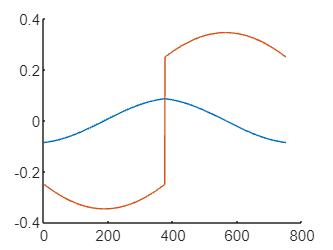


Delta = H0.*H1n-H0n.*H1;

figure;
%subplot(2,1,1);
hold on;
plot(real(Delta))
plot(imag(Delta))

%stem(-20:20,real(Delta(100-20:100+20)),'LineWidth',2,'Color','r');

% lgd = legend('H_0(z)','H_1(z)');
% lgd.FontSize = 12;
% xlim([0 L/2]*1000)
% grid on;
% grid minor;
% set(gca,'FontSize',24)
% set(gca,'linewidth',1.5)
% title('\Delta(z)')

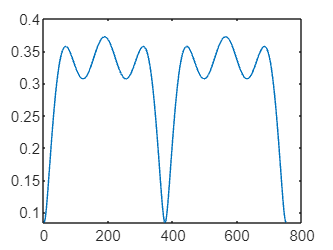

delta_temp = fftshift(ifft(ifftshift(Delta)));
delta = delta_temp(N-5:N+5);
%figure; stem(delta)
[z,p,k] = tf2zpk(delta,1);
%abs(z)
[z,p,k] = tf2zpk(polystab(delta)*norm(delta)/norm(polystab(delta)),1);
%abs(z)
for i = 1:10
    if abs(z(i)) >0.95
        z(i) = z(i)*0.95/abs(z(i));
    end
end
%abs(z)
delta_st = zp2tf(z,p,k);
%figure; stem(delta_st);
delta_s = zeros(2*N-1,1);
delta_s(N-5:N+5) = delta_st;
Delta_s = fftshift(fft(ifftshift(delta_s)));
figure;
plot(abs(Delta_s));

H0m = ifftshift(H0)'*ones(1,750);
H1m = ifftshift(H1)'*ones(1,750);

U0 = a_det.*H0m;
U1 = a_det.*H1m;

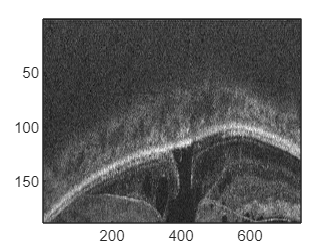

u0 = ifft(U0);
u0d = u0(1:2:end-1,:);
u1 = ifft(U1);
u1d = u1(1:2:end-1,:);

U0d = fft(u0d);
U1d = fft(u1d);

figure;
imagesc(abs(U0d(1:N/2,:))); colormap gray;

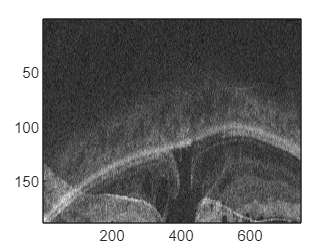

figure;
imagesc(abs(U1d(1:N/2,:))); colormap gray;


% figure; hold on;
% plot(lvec(1:N/2-1)*1000,abs(U0d(1:N/2-1)),'LineWidth',3,'Color','k');
% plot(lvec(1:N/2-1)*1000,abs(U1d(1:N/2-1)),'LineWidth',3,'Color','r');
% 
% lgd = legend('First channel','Second channel');
% lgd.FontSize = 36;
% xlim([0 L/2]*1000)
% % grid on;
% % grid minor;
% set(gca,'FontSize',44)
% set(gca,'linewidth',2.5)
% %title('Filter')
% xlabel('Distance (mm)')
% ylabel('Fourier Transform')
% set(gcf,'Position',[0 0 1200 650])

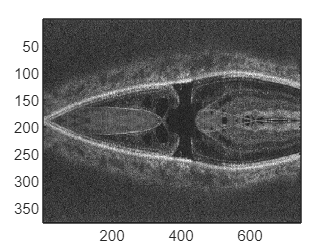

u0u = zeros(2*N-2,750);
u0u(1:2:2*N-2,:) = u0d;
u1u = zeros(2*N-2,750);
u1u(1:2:2*N-2,:) = u1d;

U0u = fft(u0u);
U1u = fft(u1u);

figure;
imagesc(abs(U0u(1:N,:))); colormap gray;

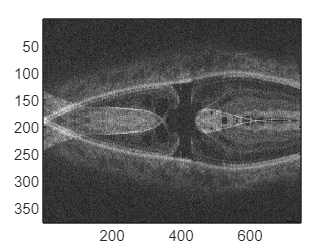

figure;
imagesc(abs(U1u(1:N,:))); colormap gray;


% figure; hold on;
% plot(lvec(1:N-1)*1000,abs(U0u(1:N-1)),'LineWidth',2,'Color','r');
% plot(lvec(1:N-1)*1000,abs(U1u(1:N-1)),'LineWidth',2,'Color','k');
% lgd = legend('First channel','Second channel');
% lgd.FontSize = 12;
% %xlim([0 L/2]*1000)
% % grid on;
% % grid minor;
% set(gca,'FontSize',24)
% set(gca,'linewidth',1.5)
% %title('Filter')
% xlabel('Distance (mm)')
% set(gcf,'Position',[0 0 1200 600])

F0 = ifftshift(H1n./Delta_s');
F1 = ifftshift(-H0n./Delta_s');
% figure; hold on;
% plot(lvec(1:N-1)*1000,real(F0(1:N-1)));
% plot(lvec(1:N-1)*1000,real(F1(1:N-1)));

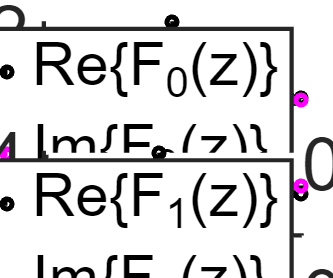

f0 = fftshift(ifft(F0));
f1 = fftshift(ifft(F1));


figure;
subplot(2,1,1);
hold on;
stem(-10:10,real(f0(N-5-10:N-5+10)),'LineWidth',3,'Color','k');
stem(-10:10,imag(f0(N-5-10:N-5+10)),'LineWidth',3,'Color','m');

lgd = legend('Re\{F_0(z)\}','Im\{F_0(z)\}');
lgd.FontSize = 36;
%xlim([0 L/2]*1000)
% grid on;
% grid minor;
set(gca,'FontSize',44)
set(gca,'linewidth',2.5)
%title('Filter')


subplot(2,1,2);
hold on;
stem(-10:10,real(f1(N-5-10:N-5+10)),'LineWidth',3,'Color','k');
stem(-10:10,imag(f1(N-5-10:N-5+10)),'LineWidth',3,'Color','m');

lgd = legend('Re\{F_1(z)\}','Im\{F_1(z)\}');
lgd.FontSize = 36;
%xlim([0 L/2]*1000)
% grid on;
% grid minor;
set(gca,'FontSize',44)
set(gca,'linewidth',2.5)
%title('Filter')
xlabel('z')
set(gcf,'Position',[0 0 1200 1000])
yticks([-0.4 0 0.4])

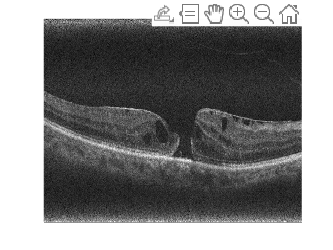

F0m = ifftshift(F0)'*ones(1,750);
F1m = ifftshift(F1)'*ones(1,750);
Yc = ifftshift(F0m(1:2*N-2,:).*U0u+F1m(1:2*N-2,:).*U1u,1);
%yc = fftshift(fft(Yc),1);
figure;
imagesc(abs(Yc(1:N,:))); colormap gray;
%title('Reconstructed - Full depth')
axis off

% figure;hold on;
% plot(fvec(1:end-1)/1e12,real(yc),'LineWidth',2,'Color','b')
% ycn = yc./S2(1:end-1)';
% Ycn = ifft(ycn);